# **Test 2 Solutions**

## **Problem 1**

#### Version 1

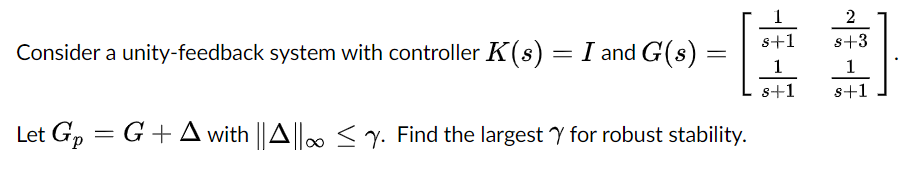

This is a straight application of RS.  For additive uncertainty, I simply need to find the infinity norm of $M = KS$.

s = tf('s');
G = [1/(s+1) 2/(s+3);1/(s+1) 1/(s+1)];
K = eye(2);
S = inv(eye(2)+G*K);
normM = norm(K*S,'inf')

normM = 1.1515

Therefore, the largest uncertainty size that can be maintained is the inverse of the norm, or

gamma = 1/normM

gamma = 0.8684

You could of course have also used a brute-force computational approach.

#### Version 2

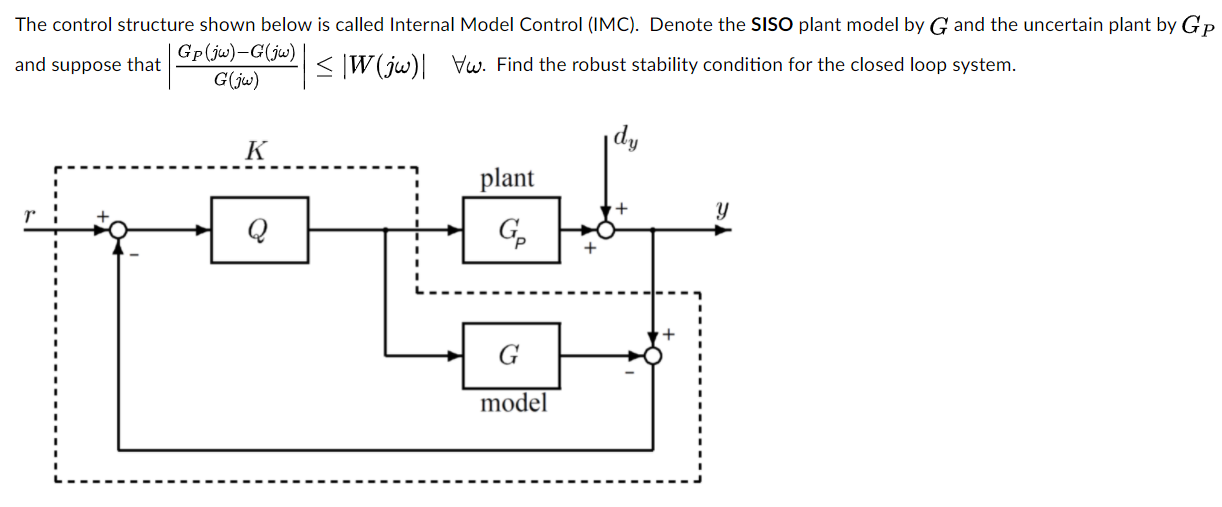

This is basically a block diagram reduction problem.  First identify that the condition implies multiplicative uncertainty.  Then redraw the block diagram and reduce it into the $M-\Delta$ form.

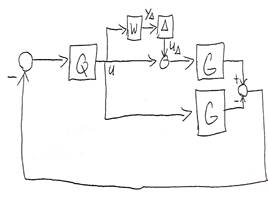

From here we have $y_\Delta = W u$, and following around the loop we have


$$u = -Q(-Gu+G(u_\Delta+u)) = -GQu_\Delta$$


Therefore $M = -GQW$, and the test for robust stability is 


$$RS \iff \| GWQ \|_\infty <1$$


#### Version 3

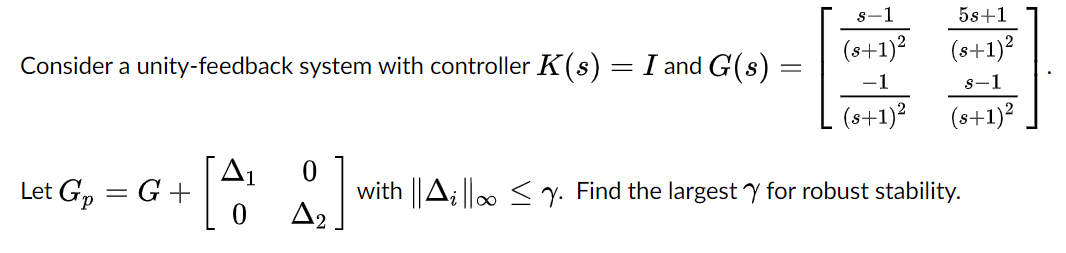

For this problem we need to compute $\mu$ given the structure of the uncertainty.

s = tf('s');
G = [(s-1)/(s+1)^2 (5*s+1)/(s+1)^2;-1/(s+1)^2 (s-1)/(s+1)^2];
K = eye(2);
D1 = ultidyn('d1',1);
D2 = ultidyn('d2',1);
S = inv(eye(2)+(G+[D1 0;0 D2])*K);

Now check the nominal stability.

isstable(S.NominalValue)

ans = logical
   1


That really just says that the problem was well-posed.  Now compute $\mu$.

stabmarg = robuststab(S);
mu = 1/stabmarg.LowerBound;

Therefore, the largest uncertainty size that can be maintained is the inverse of the norm, or

gamma = 1/mu

gamma = 0.5429

You could of course have also used a brute-force computational approach.

## **Problem 2**

#### Version 1

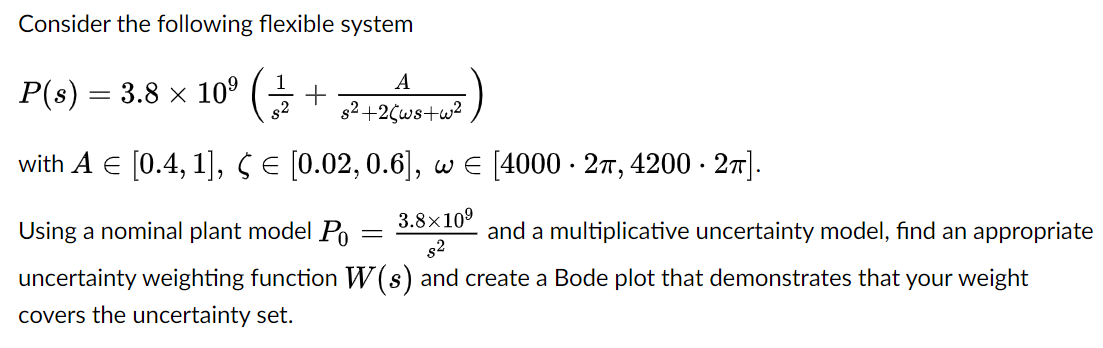

First I will make the plant.

A = ureal('A',0.7,'plusminus',0.3);
zeta = ureal('zeta',(0.02+0.6)/2,'range',[0.02,0.6]);
w = ureal('w',4100*2*pi,'plusminus',100*2*pi);
P = 3.8e9*(1/s^2+A/(s^2+2*zeta*w*s+w^2));
P0 = 3.8e9/s^2;

Now use ucover to fit the multiplicative uncertainty model.

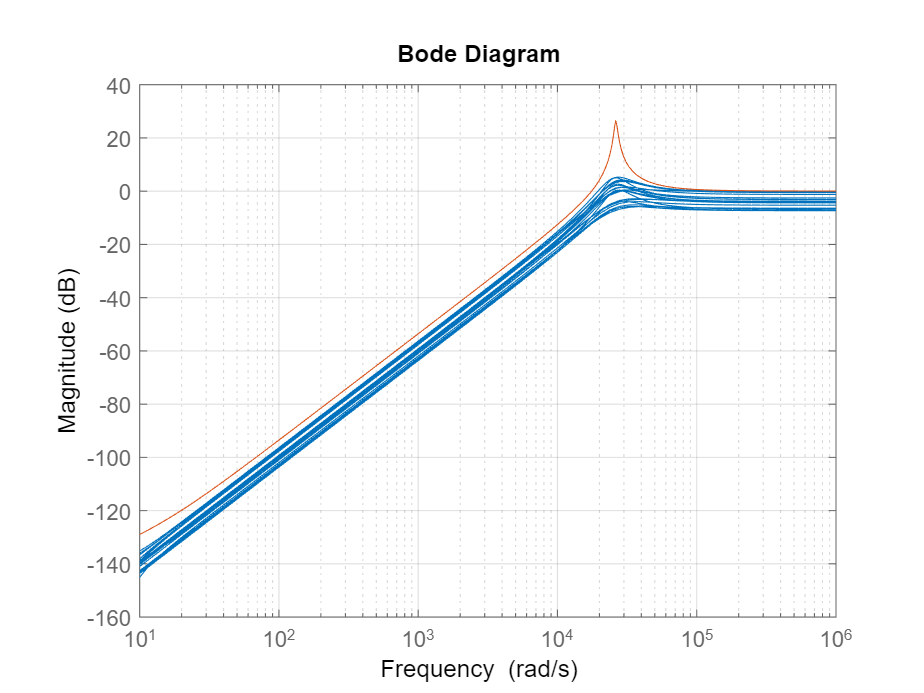

[Punc,info] = ucover(usample(P,50),P0,4);
bodemag(P/P0-1,info.W1,{10,1e6})

The stuff at low frequency is numerical nonsense.  The fit is in fact good.

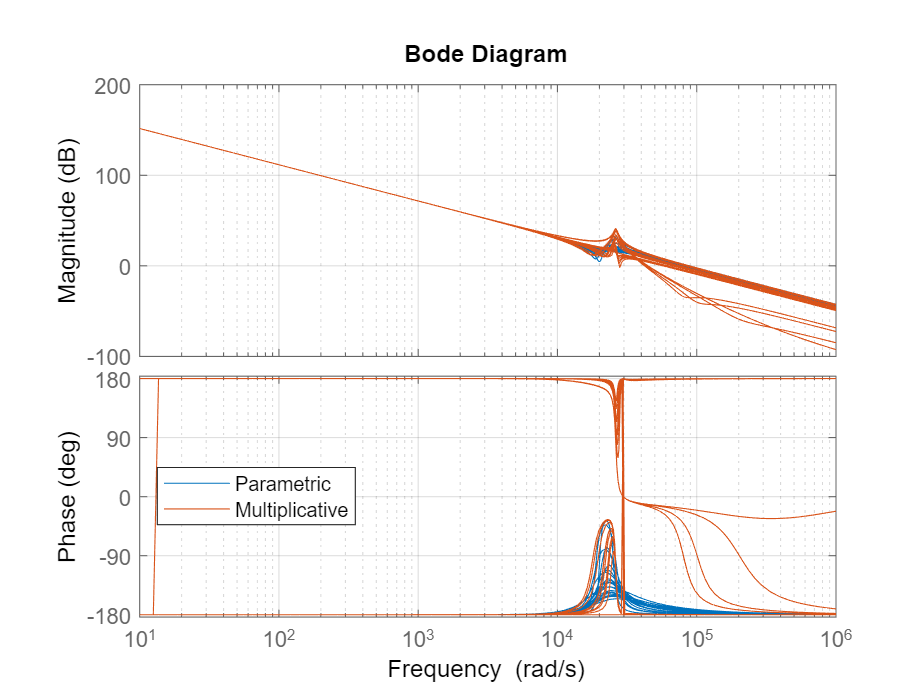

bode(P,Punc,{10,1e6});legend('Parametric','Multiplicative','location','best')

#### Version 2

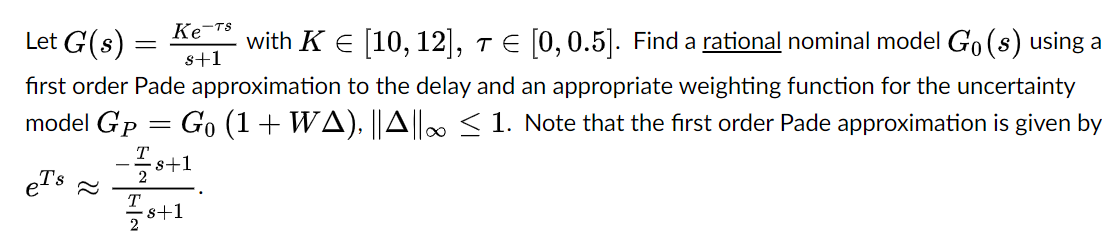

Start by building the plant.

K = ureal('K',11,'plusminus',1);
tau = ureal('tau',0.25,'plusminus',0.25);
G = K*(-tau/2*s+1)/(tau/2*s+1)/(s+1);
Gnom = tf(G.NominalValue)

Gnom =
 
   -11 s + 88
  -------------
  s^2 + 9 s + 8
 
Continuous-time transfer function.



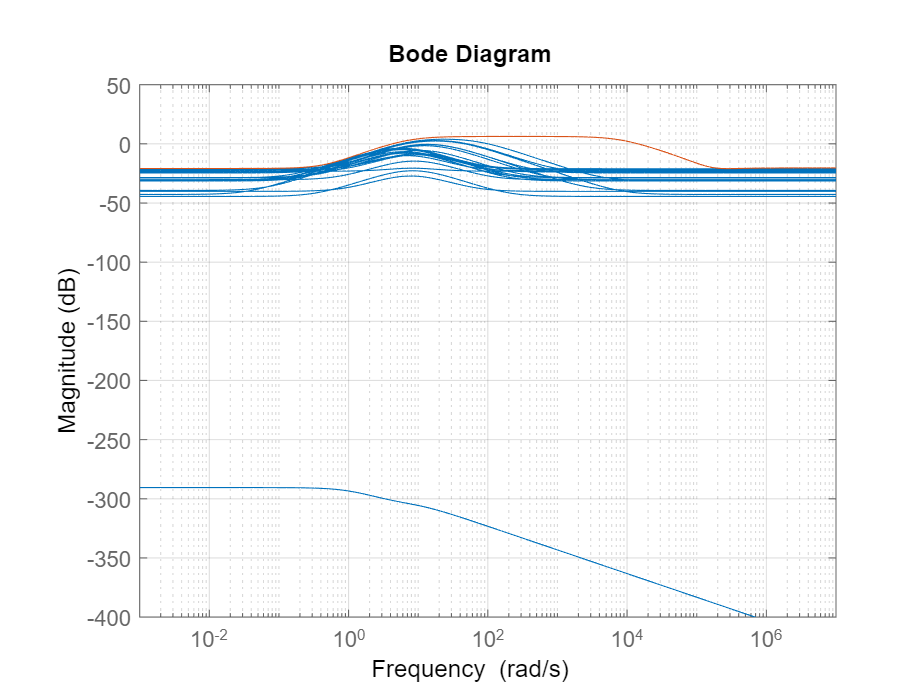

[Gunc,info] = ucover(usample(G,100),Gnom,4);
bodemag(G/Gnom-1,info.W1)

Note that Matlab does not support using uncertain variables inside of a time delay.  We could increase the order of the Pade approximation to get a better fit if we would like, but there's not too much else to do.

## **Problem 3**

#### **Version 1**

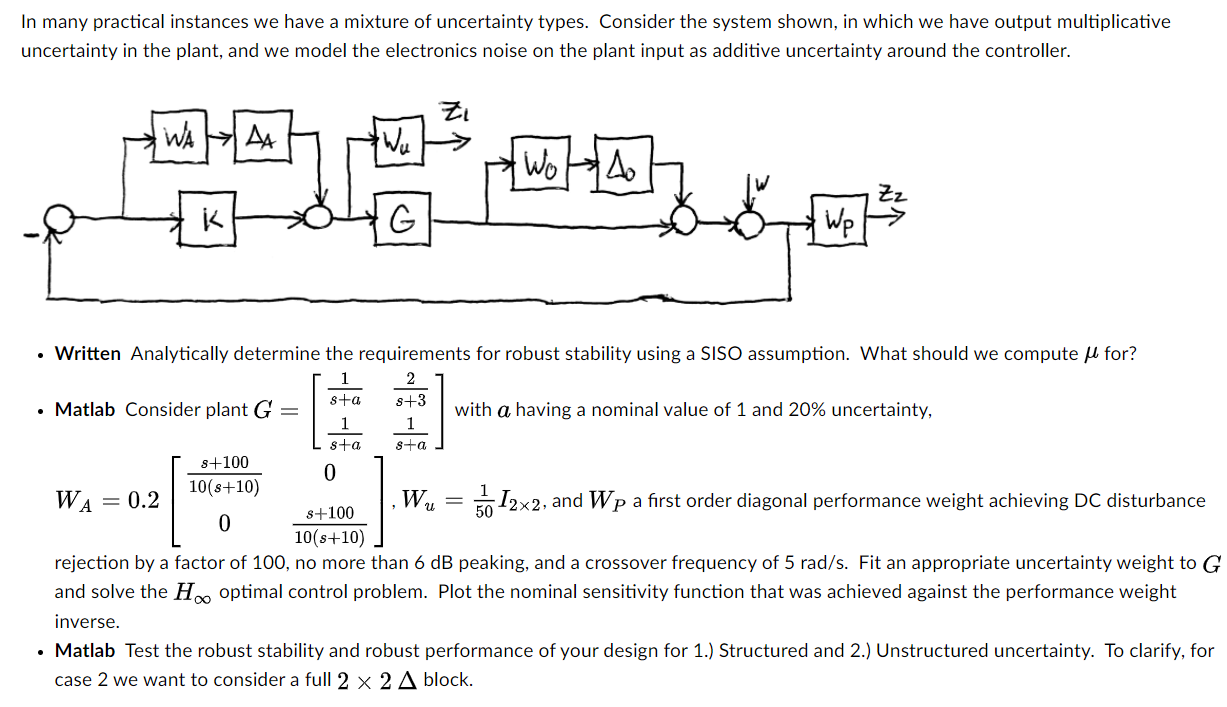

Part a

For this part I will assume SISO.  The problem is basically just to find $M$ and work from there.  Denote by $Q$ the input to $K$.


$$Q = -(u_{\Delta O}+G(u_{\Delta A}+KQ))$$



$$Q = -Su_{\Delta O}-SGu_{\Delta_A}$$



$$y_{\Delta A} = -W_ASu_{\Delta O}-W_ASGu_{\Delta A}$$



$$y_{\Delta O} = W_OG(u_{\Delta A}+KQ)=W_OGu_{\Delta A}+W_OGK(-Su_{\Delta O}-SGu_{\Delta A})$$



$$y_{\Delta O} = -W_OTu_{\Delta O}+W_OSGu_{\Delta A}$$


Now we have


$$M = \pmatrix{-W_A S G & -W_AS \cr W_OSG & -W_OT}$$


Now, for a diagonal $\Delta$, we have


$$|I-M\Delta| = |\pmatrix{I+W_ASG\Delta_1 & W_AS\Delta_2 \cr -W_oSG\Delta_1 & I+W_oT\Delta_2}| = 0$$


Completing the determinant we have


$$I+W_oT\Delta_2+W_ASG\Delta_1+W_ASG\Delta_1W_oT\Delta_2+W_oSG\Delta_1W_AS\Delta_2 = 0$$


Given the SISO assumption and the fact that T = 1-S we have


$$1+W_oT\Delta_2+W_ASG\Delta_1+W_AW_oSG\Delta_1\Delta_2 = 0$$


This does not have a clean solution unfortunately, i.e. we cannot get a simple form like we had in prior examples.  Perhaps the easiest way to write this as


$$\mu\pmatrix{-W_ASG & -W_AS \cr W_OSG & -W_OT}<1$$


Part b

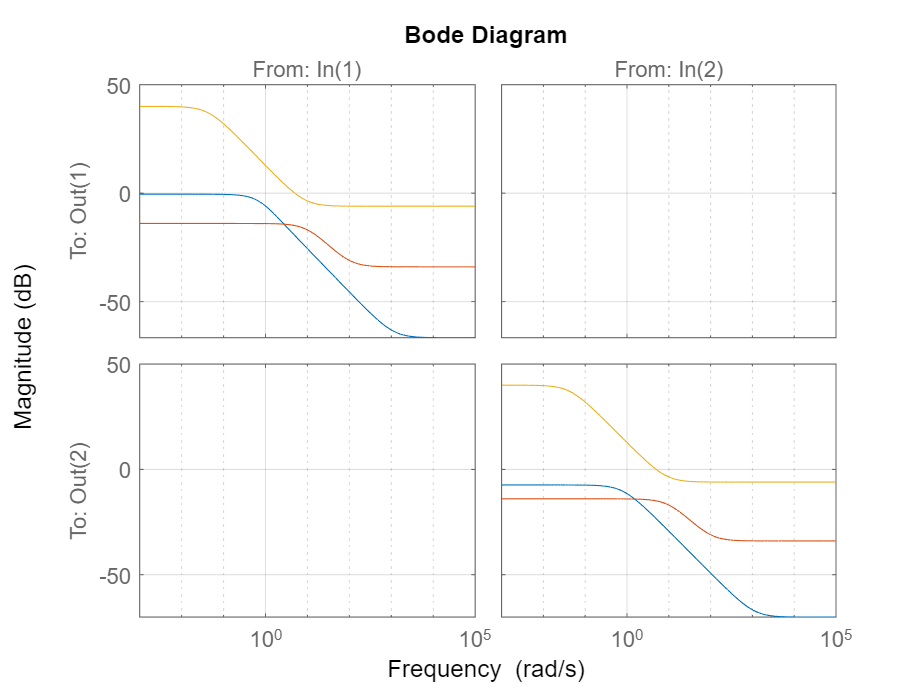

s = tf('s');
a = ureal('a',1,'Percentage',20);
G = [1/(s+a) 2/(s+3);1/(s+a) 1/(s+a)];
Gnom = G.NominalValue;
[Gmult,info] = ucover(usample(G,50),Gnom,[2 2],'OutputMult');
WT = info.W1;
WA = 0.2*[(s+100)/10/(s+10) 0;0 (s+100)/10/(s+10)];
Wu = 1/50*eye(2);
Wp = makeweight(100,5,1/2)*eye(2);
bodemag(WT,WA,Wp)

systemnames = 'WA WT Wu Wp Gnom';
inputvar = '[u_DA{2};u_DO{2};W{2};u{2}]';
outputvar = '[WA;WT;Wu;Wp;-u_DO-Gnom-W]'; 
input_to_WA = '[-u_DO-Gnom-W]';
input_to_WT = '[Gnom]';
input_to_Wu = '[u+u_DA]';
input_to_Wp = '[Gnom+u_DO+W]';
input_to_Gnom = '[u+u_DA]';
cleanupsysic = 'yes';
P = sysic;
[K,CL,gam] = hinfsyn(P,2,2);
gam

gam = 7.0820

NOTE:  There were not explicit requirements on how to present the answer.

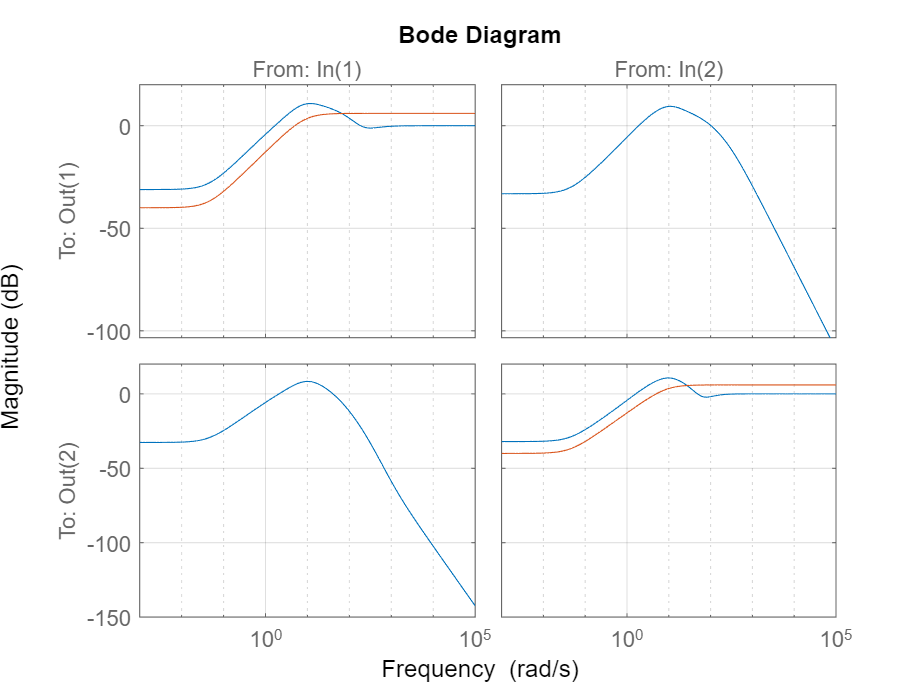

bodemag(eye(2)-feedback(Gnom*K,eye(2)),inv(Wp))

Part c

To handle unstructured uncertainty I'll use the infinity norm.  Importantly, we do not want to have separate $\Delta$'s here, otherwise it's structured.

M = CL(1:4,1:4);
RS_unstruct = norm(M,'inf')

RS_unstruct = 0.9941

We definitely have RS, so it makes sense to check RP.  For this I do have to compute $\mu$ 

N = lft(P,K);
Nunc = lft(ultidyn('dfull',[4,4]),N);
RPbnd= robustperf(Nunc);
RP_unstruct = 1/RPbnd.LowerBound

RP_unstruct = 5.8912

It was already looking bad with "gam"... clearly we do not hit it.

Now let's look at structured.  I need to rebuild my sysic using the uncertain plant.

systemnames = 'Wu Wp G';
inputvar = '[W{2};u{2}]';
outputvar = '[Wu;Wp;-G-W]'; 
input_to_Wu = '[u]';
input_to_Wp = '[G+W]';
input_to_G = '[u]';
cleanupsysic = 'yes';
Punc = sysic;
Delta = ultidyn('Delta',[2,2]);

Now I have to build the uncertain controller, and work from there.

Kunc = K+WA*Delta;
Nunc = lft(Punc,Kunc);
marg = robuststab(Nunc);
RS_struct = 1/marg.LowerBound

RS_struct = 0.3694

Again, we have RS, so we can move on to RP.

marg = robustperf(Nunc);
RP_struct = 1/marg.LowerBound

RP_struct = 5.4781

Stll no RP, but closer...

#### Version 2

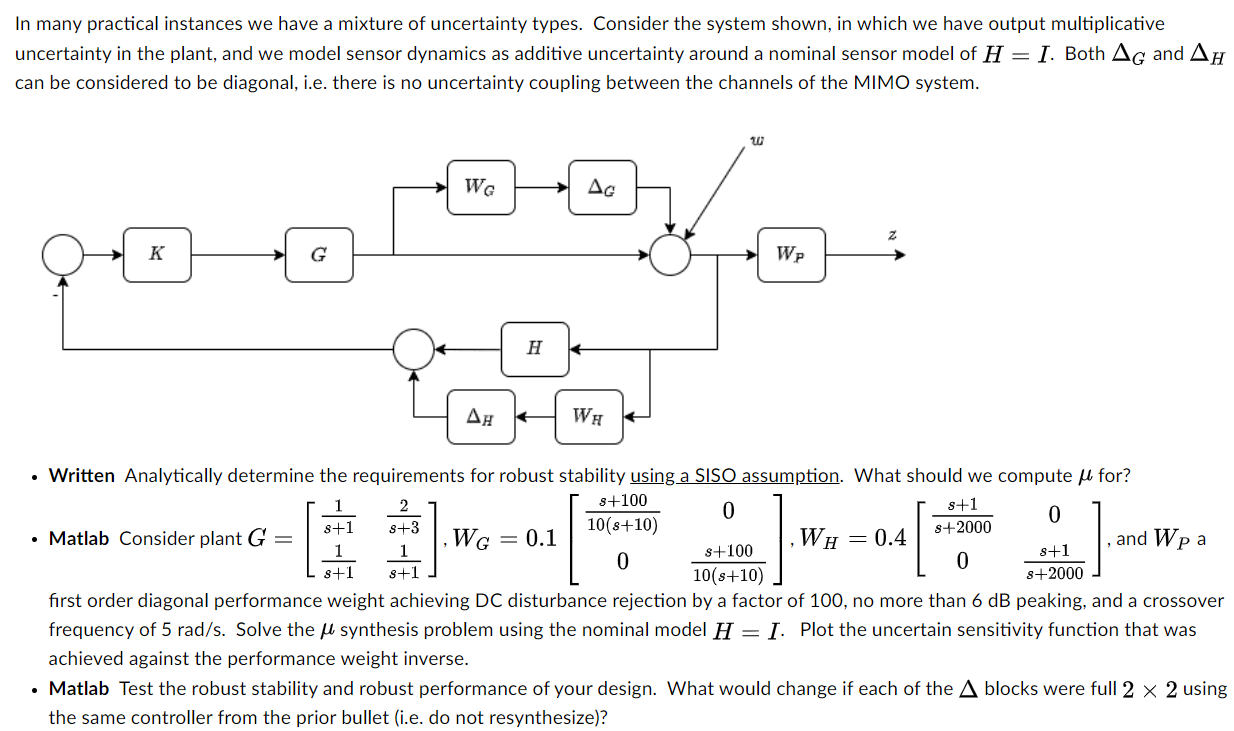

Part a

For this part I will assume SISO.  The problem is basically just to find $M$ and work from there.  


$$y_{\Delta_G} = -W_GGK\left(u_{\Delta_H}+H\left(u_{\Delta_G}+\frac{y_{\Delta_G}}{W_G}\right)\right)$$


$(1+GKH)y_{\Delta_G} = -W_GGKu_{\Delta_H}-W_GGKHy_{\Delta_G}\Rightarrow y_{\Delta_G} = -\frac{W_GGK}{1+GKH}u_{\Delta_H}-\frac{W_GGKH}{1+GKH}u_{\Delta_G}$.


$$y_{\Delta_H} = W_H\left(u_{\Delta_G}-GK\left(u_{\Delta_H}+\frac{H}{W_H}y_{\Delta_H}\right)\right)$$



$$(1+GKH)y_{\Delta_H} = W_Hu_{\Delta_G}-W_HGKu_{\Delta_H}\Rightarrow y_{\Delta_H} = \frac{W_H}{1+GKH}u_{\Delta_G}-\frac{W_HGK}{1+GKH}u_{\Delta_H}$$


Now we have


$$M = \pmatrix{-\frac{W_GGKH}{1+GKH} & -\frac{W_GGK}{1+GKH} \cr \frac{W_H}{1+GKH} & -\frac{W_HGK}{1+GKH}}$$


  Perhaps the easiest way to write this as

$\mu(M)<1$.

Part b

To solve this problem I have to build the system and the uncertain elements, then build the generalized plant.

s = tf('s');
%Uncertain plant
DG1 = ultidyn('DG1',1);
DG2 = ultidyn('DG2',1);
Gunc = (eye(2)+0.1*(s+100)/10/(s+10)*eye(2)*[DG1 0;0 DG2])*[1/(s+1) 2/(s+3);1/(s+1) 1/(s+1)];
%Uncertain sensor
DH1 = ultidyn('DH1',1);
DH2 = ultidyn('DH2',1);
Hunc = eye(2)+0.4*(s+1)/(s+2000)*eye(2)*[DH1 0;0 DH2];
%Performance weight
Wp = makeweight(100,3,0.5)*eye(2);
%Generalized plant
systemnames = 'Wp Gunc Hunc';
inputvar = '[w{2};u{2}]';
outputvar = '[Wp;-Hunc]'; 
input_to_Wp = '[w+Gunc]';
input_to_Gunc = '[u]';
input_to_Hunc = '[w+Gunc]';
cleanupsysic = 'yes';
P = sysic;
[K,muperf] = musyn(P,2,2);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           3.912        3.868        3.898             4
    2           3.233        3.225         3.26            16
    3           3.227        3.197        3.231            20
    4           3.224        3.197        3.225            28

Best achieved robust performance: 3.2



muperf

muperf = 3.1966

NOTE:  There were not explicit requirements on how to present the answer.

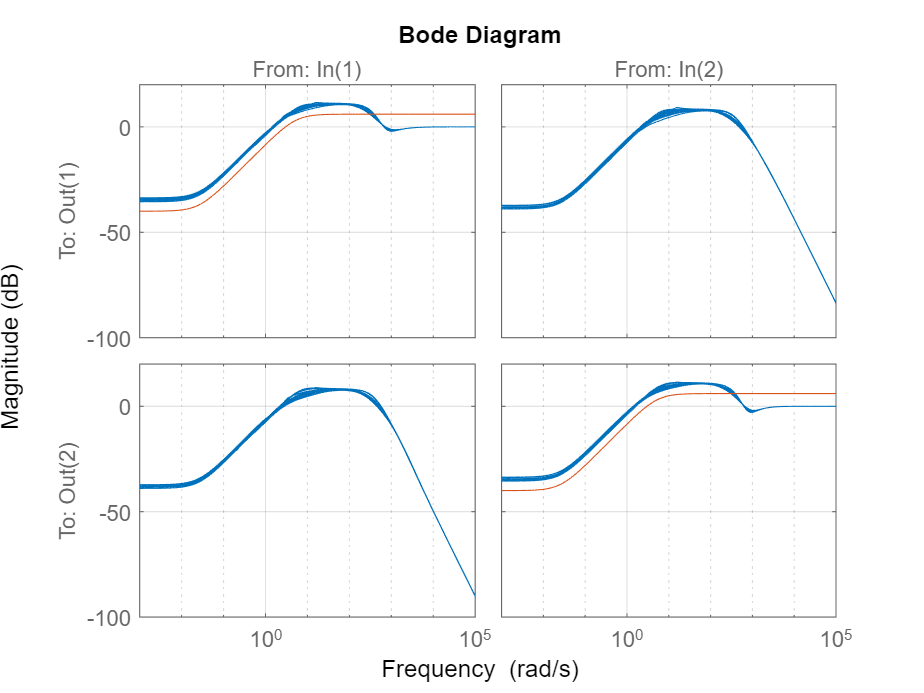

bodemag(eye(2)-feedback(Gunc*K,Hunc),inv(Wp))

Part c

The answer for robust performance is directly computed by $\mu$, so we immediately know that the system **does not have RP**.

We should check for RS though.

N = lft(P,K);
bnd = robstab(N);
mu_stab = 1/bnd.LowerBound

mu_stab = 0.3222

We definitely **do have RS.**

Now, let's consider the case where the blocks are full.  For starters, there is no way that we will get RP back, so it **does not have RP**.  The only question is whether we will keep RS.

%Uncertain plant
DGfull = ultidyn('DGfull',[2,2]);
Gunc = (eye(2)+0.1*(s+100)/10/(s+10)*eye(2)*DGfull)*[1/(s+1) 2/(s+3);1/(s+1) 1/(s+1)];
%Uncertain sensor
DHfull = ultidyn('DHfull',[2,2]);
Hunc = eye(2)+0.4*(s+1)/(s+2000)*eye(2)*DHfull;
%Performance weight
Wp = makeweight(100,3,0.5)*eye(2);
%Generalized plant
systemnames = 'Wp Gunc Hunc';
inputvar = '[w{2};u{2}]';
outputvar = '[Wp;-Hunc]'; 
input_to_Wp = '[w+Gunc]';
input_to_Gunc = '[u]';
input_to_Hunc = '[w+Gunc]';
cleanupsysic = 'yes';
P = sysic;
bnd = robstab(lft(P,K));
mu_stab_full = 1/bnd.LowerBound

mu_stab_full = 0.3222

Nothing has changed - we **still have RS.**

## **Problem 4**

#### **Version 1**

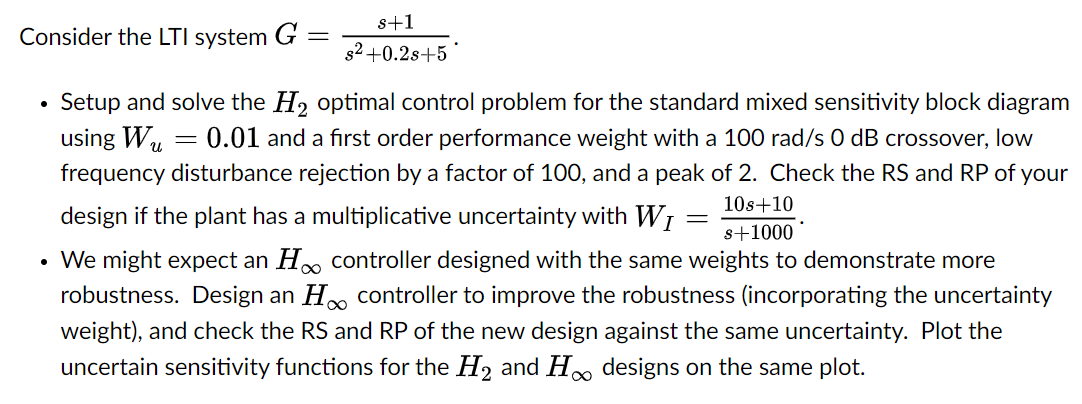

Part a

s = tf('s');
G = (s+1)/(s^2+0.2*s+5);
Wp = makeweight(100,100,1/2);
Wu = 0.01;
P2 = augw(G,Wp,Wu,[]);
[K2,~,K2Norm] = h2syn(P2,1,1);

del = ultidyn('del',[1 1]);
WI = (10*s+10)/(s+1000);
Gunc = (1+WI*del)*G;
T2 = feedback(G*K2,1);
S2 = 1-T2;
RS = norm(WI*T2,'inf')

RS = 0.6041

**We have RS** - need to check RP.  A necessary condition is that the uncertain sensitivity function has RP.

marg = robustperf(Wp/(1+Gunc*K2));
RP_sense = 1/marg.LowerBound

RP_sense = 1.9463

Because the sensitivity function does not meet RP, there is no way that the full $N$ will meet it.  So **it does not have RP.**

Part b

[Kinf,~,GAM] = mixsyn(G,Wp,Wu,WI);
Tinf = feedback(G*Kinf,1);
Sinf = 1-Tinf;
RS = norm(WI*Tinf,'inf')

RS = 0.6973

We have RS - need to check RP.  A necessary condition is that the uncertain sensitivity function has RP.

marg = robustperf(Wp/(1+Gunc*Kinf));
RP_sense = 1/marg.LowerBound

RP_sense = 1.4091

If the sensitivity doesn't meet requirements, there's no need to check on the overall system.  Note that I would have to check my other requirements is this were <1.  Finally, I'll plot the uncertain sensitivity functions.

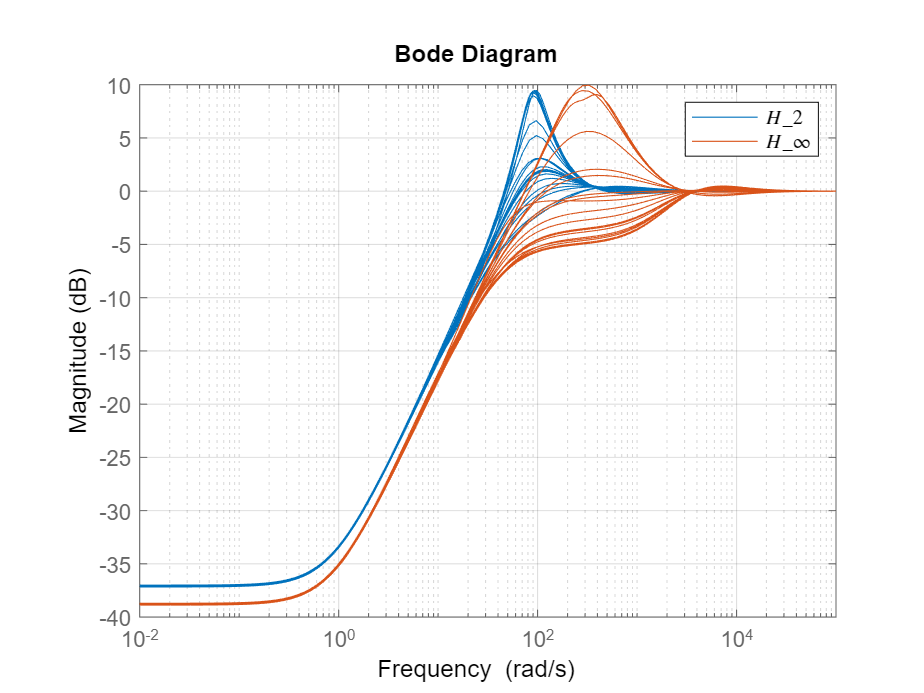

bodemag(1/(1+Gunc*K2),1/(1+Gunc*Kinf))
legend('$H_2$','$H_\infty$','Interpreter','latex')

The $H_\infty$ clearly appears to have better performance overall.

#### **Version 2**

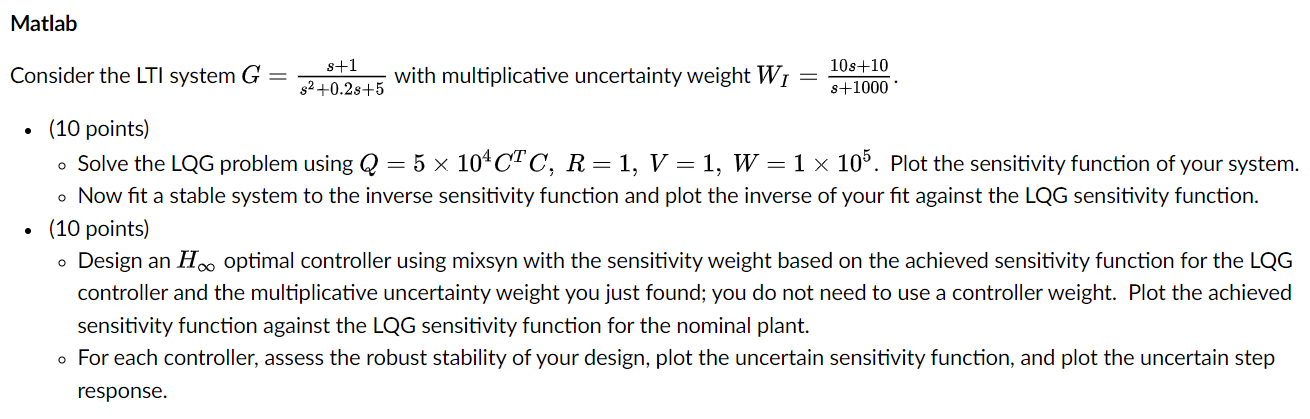

Part a

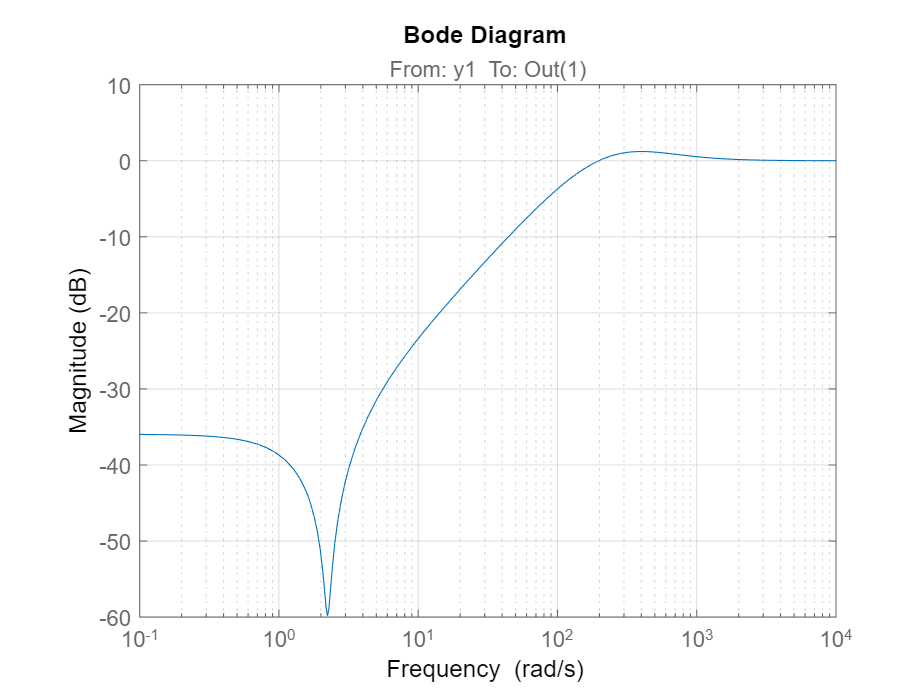

G = ss((s+1)/(s^2+0.2*s+5));
Qxu = blkdiag(50000*G.C'*G.C,1);
Qwv = blkdiag(100000*eye(2),1);
Klqg = -lqg(G,Qxu,Qwv);
del = ultidyn('del',[1 1]);
WI = (10*s+10)/(s+1000);
Gunc = (1+WI*del)*G;
Tlqg = feedback(G*Klqg,1);
Slqg = 1-Tlqg;
bodemag(Slqg)

Now fit the sensitivity function.

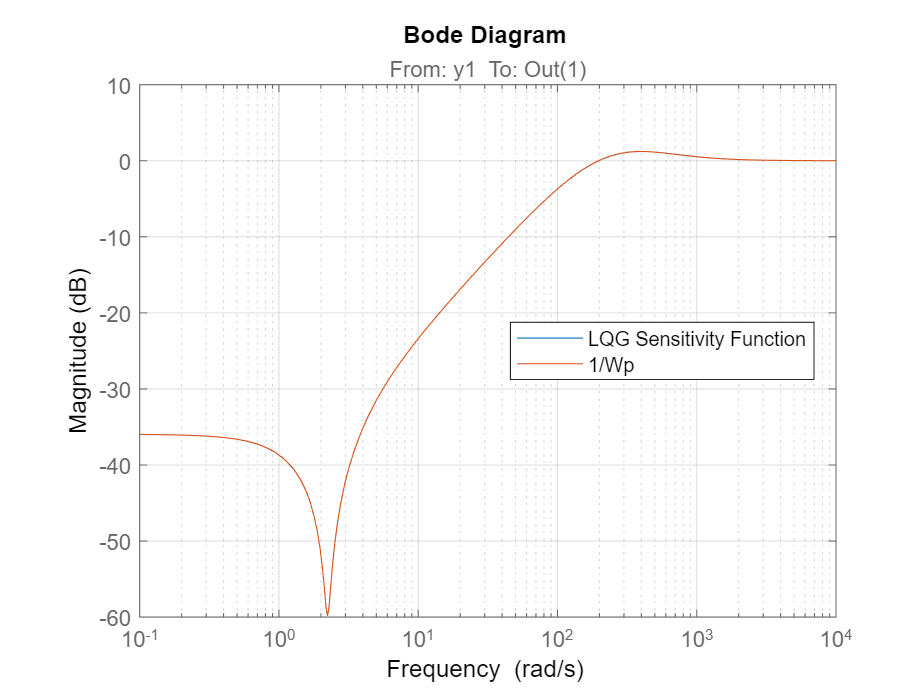

Wp = fitmagfrd(frd(1/Slqg,logspace(-5,4)),4);
bodemag(Slqg,1/Wp)
legend('LQG Sensitivity Function','1/Wp','Location','best')

Part b

Firstly design the controller.

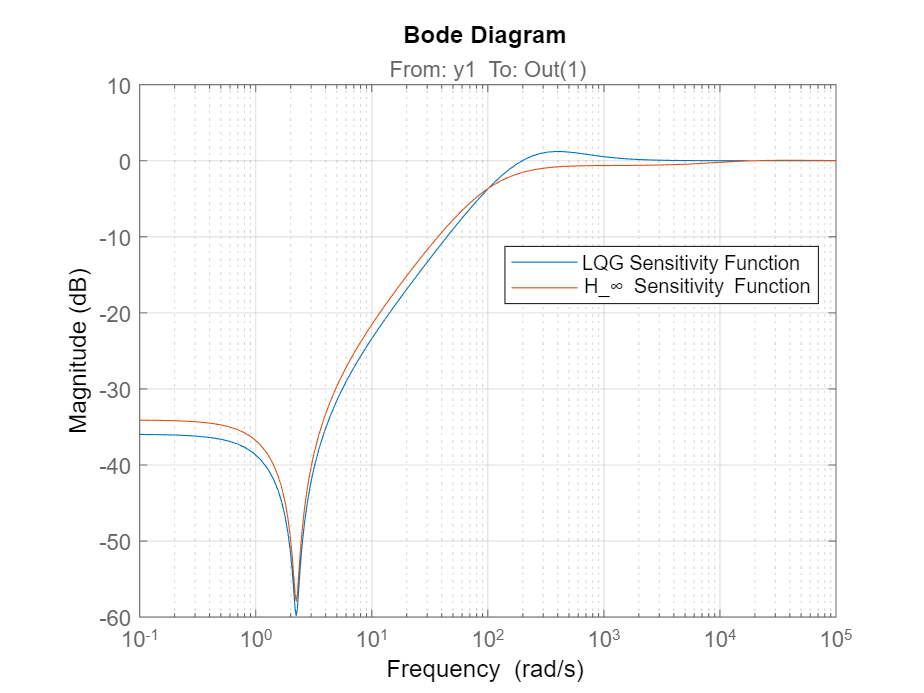

[Kinf,~,GAM] = mixsyn(G,Wp,[],WI);
Tinf = feedback(G*Kinf,1);
Sinf = 1-Tinf;
bodemag(Slqg,Sinf)
legend('LQG Sensitivity Function','H_\infty Sensitivity Function','Location','best')

Now look at robust stability.

LQG

RS_LQG = norm(WI*Tlqg,'inf')

RS_LQG = 1.3421

RS_INF = norm(WI*Tinf,'inf')

RS_INF = 0.9599

Thus LQG does not have RS, but $H_\infty$ synthesis does have RS.

Finally, I'll plot the uncertain sensitivity functions and step responses.

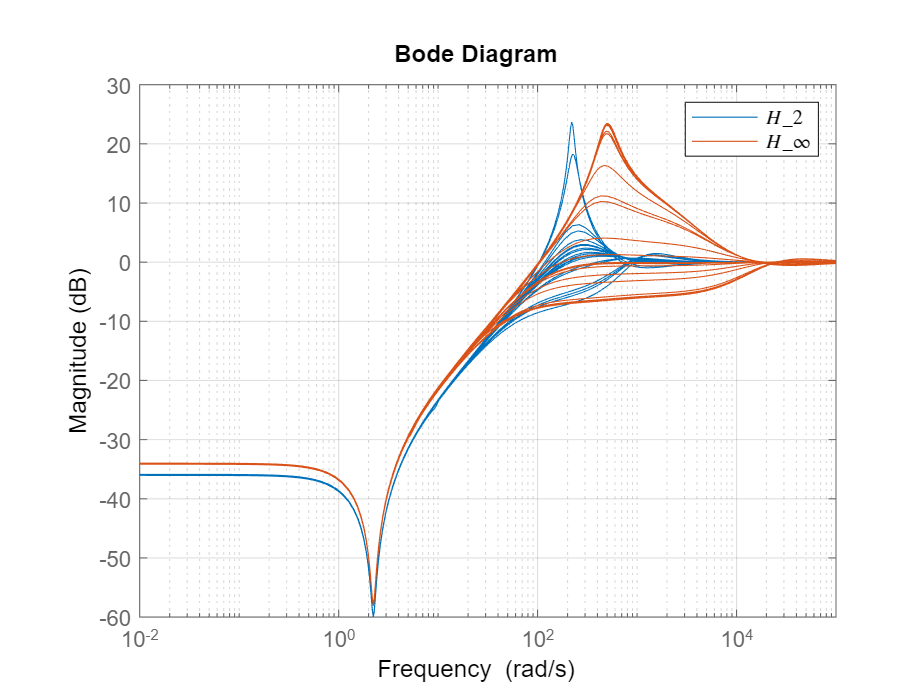

bodemag(1/(1+Gunc*Klqg),1/(1+Gunc*Kinf))
legend('$H_2$','$H_\infty$','Interpreter','latex')

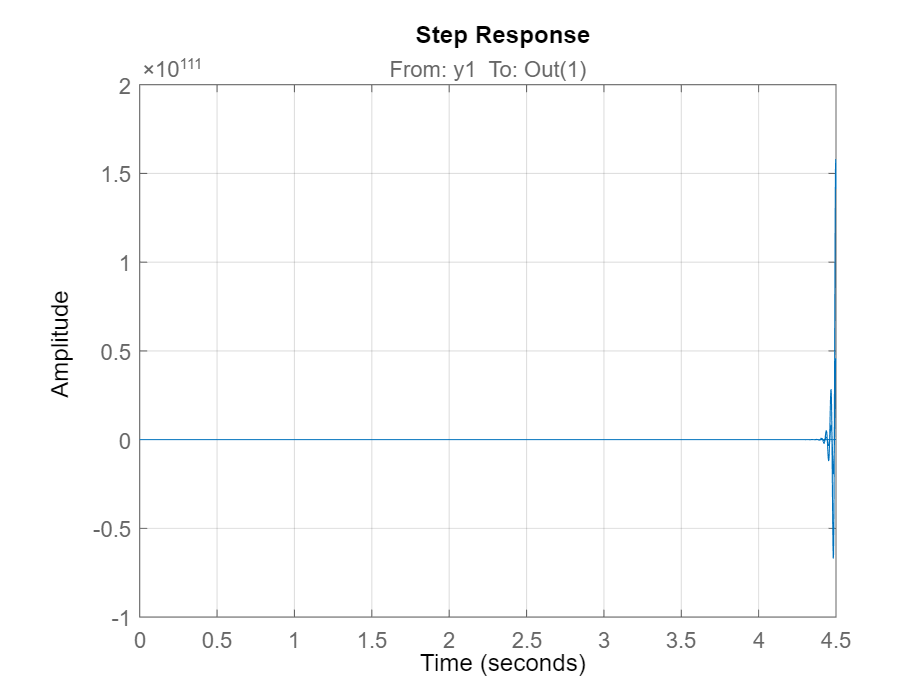

step(feedback(Gunc*Klqg,1))

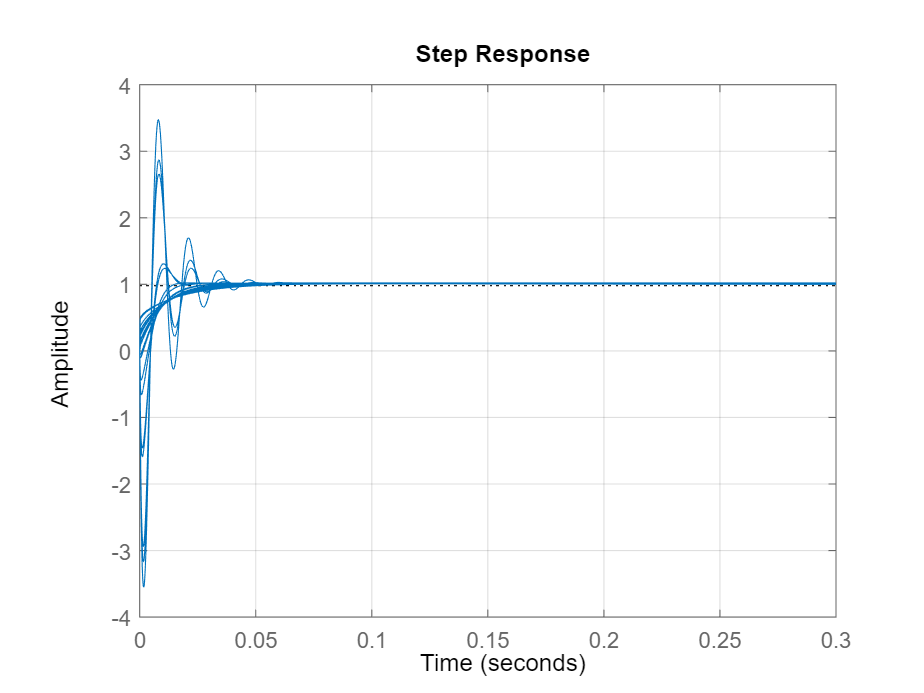

step(feedback(Gunc*Kinf,1))

The $H_\infty$ clearly appears to have better performance overall.

## Problem 5

#### Version 1

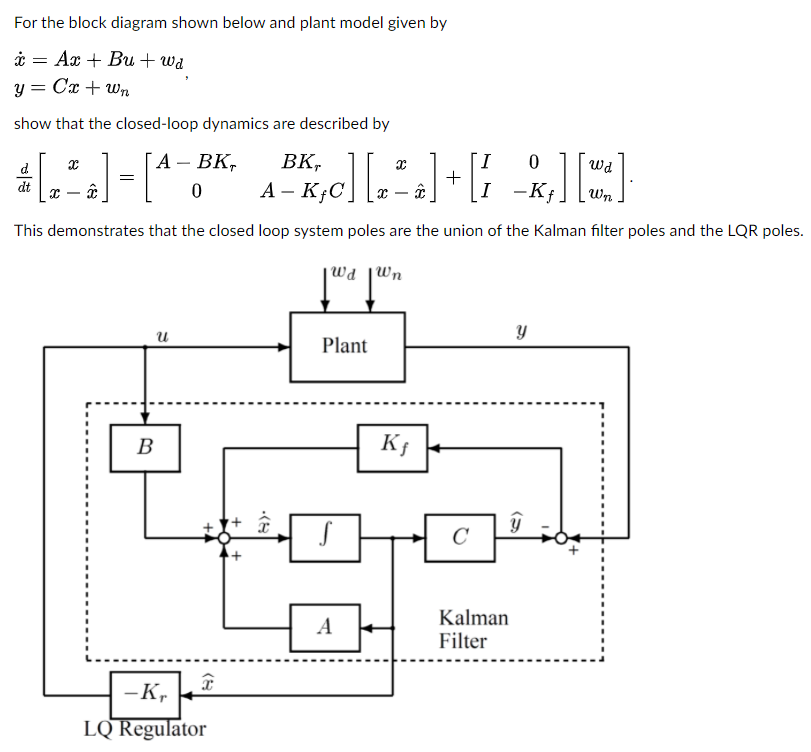

This is a block diagram manipulation problem.  Effectively we just need to find walk around the loop.


$$u = -K_r\hat{x}\Rightarrow \dot{x} = Ax-BK_r\hat{x}+w_d$$



$$\dot{\hat{x}} = A\hat{x}+Bu+K_f(Cx+w_n-C\hat{x}) = (A-BK_r)\hat{x}+K_fC(x-\hat{x})+K_f w_n$$$


Use the change of variables $\tilde{x} = x-\hat{x}$.  Then


$$\dot{x} = Ax-BK_r(x-\tilde{x})+w_d = (A-BK_r)x+BK_r\tilde{x}+w_d$$



$$\dot{x}-\dot{\tilde{x}}=(A-BK_r)(x-\tilde{x})+K_fC\tilde{x}\Rightarrow\dot{\tilde{x}} +K_fw_n= \dot{x}-(A-BK_r)x+(A-BK_r)\tilde{x}-K_fC\tilde{x}-K_fw_n$$


Substituting for $\dot{x}$ yields


$$\dot{\tilde{x}} = (A-K_r)x+BK_r\tilde{x}+w_d-(A-BK_r)x+(A-BK_r)\tilde{x}-K_fC\tilde{x}-K_fw_n = (A-K_fC)\tilde{x}+w_d-K_fw_n$$


Now it's done, i.e.


$$\dot{\pmatrix{x \cr \tilde{x}}} = \pmatrix{A-BK_r & BK_r \cr 0 & A-K_fC}\pmatrix{x \cr \tilde{x}}+\pmatrix{I & 0 \cr I & -K_f}\pmatrix{w_d \cr w_n}$$


#### Version 2

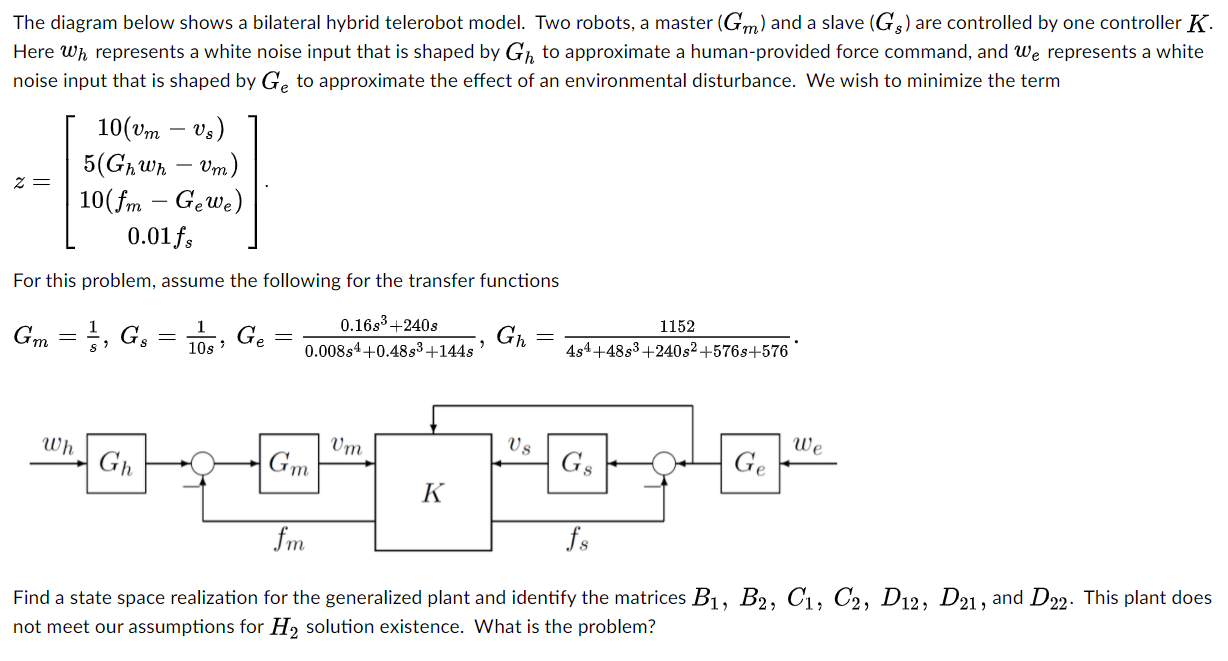

I'll use sysic to solve this problem.  First I need to get the variables up in Matlab.

s = tf('s');
Gm = 1/(s+0);
Gs = 1/10/(s+0);
Ge = (0.16*s^3+240*s)/(0.008*s^4+0.48*s^3+144*s+0);
Gh = 1152/(4*s^4+48*s^3+240*s^2+576*s+576);

Now run sysic.

systemnames = 'Gm Gs Ge Gh';
inputvar = '[wh;we;fm;fs]';
outputvar = '[10*Gm-10*Gs;5*Gh-5*Gm;10*fm-10*Ge;0.01*fs;Ge;Gs;Gm]'; 
input_to_Gm = '[Gh-fm]';
input_to_Gs = '[Ge-fs]';
input_to_Ge = '[we]';
input_to_Gh = '[wh]';
cleanupsysic = 'yes';
P = sysic;
ss(P)

ans =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8
   x1        -12      -7.5      -4.5     -2.25         0         0         0         0
   x2          8         0         0         0         0         0         0         0
   x3          0         4         0         0         0         0         0         0
   x4          0         0         2         0         0         0         0         0
   x5          0         0         0    0.0625         0         0         0         0
   x6          0         0         0         0         0       -60  3.02e-14    -35.16
   x7          0         0         0         0         0        16         0         0
   x8          0         0         0         0         0         0        32         0
   x9          0         0         0         0         0         0         0         1
   x10         0         0         0         0         0         0         0         0
   x11         0         0  

The issue is that D21 is not full rank.  Therefore the ARE's will not have a solution.